clc % clear command window
clear all % clear workspace

1. Supply path to the toolkit's "model_code" directory to "cfg" structure, and add the "common" subfolder to the MATLAB path. Also specify the general directory where results will be saved. 

% Add paths to relevant functions
cfg.model_dir = '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code'; % path to toolkit
addpath(genpath(fullfile(cfg.model_dir, 'common'))); % add common folder to path

% Specify output directory (Note - output folders for specific analyses will be created in this directory)
out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results'; 

2. For this tutorial, we'll be using parcel-based measures of regional damage and tract disconnection that are stored in text files, so we'll set cfg.modality to 'other'

% Specify data modality and supply brain mask
cfg.modality = 'other'; % predictor modality - 'lesion' or 'other' 

3. Specify general modeling options.

- cfg.model_spec - the type of model you want to fit. Here, we'll use "censemble" to select a classification tree ensemble.

- cfg.method - the ensemble method. For classification, the options are 'LSBoost', 'AdaBoostM1', 'AdaBoostM2', 'GentleBoost', 'LogitBoost', and 'Bag'. Here, we'll use 'Bag' to do bagged classification trees.

- cfg.fit_explanatory_model - flag indicating whether you want to fit a model to the full dataset. Here, we'll turn it on so that we can get estimates of predictor importance.

- cfg.optimize_hyperparams - flag indicating whether you want to use cross-validation to optimize model hyper-parameters. Here, we'll turn it on. This will optimize several parameters that can be found in the function get_default_model_cfg(). 

- cfg.cross_validation - flag indicating whether you want to use cross-validation to estimate predictive performance and out-of-sample generalization. If hyper-parameter optimization is selected, then this will perform nested cross-validation. Since ensemble models are primarily used for predictive analyses, we will turn this on. This will also provide an estimate of the statistical significance of the explanatory model (i.e., cross-validation correlation).

- cfg.bootstrap - flag indicating whether you want to use bootstrapping to estimate statistical significance of model coefficients and/or to estimate confidence intervals for multivariate explanatory models. This is not implemented for ensemble models, so we will turn it off.

- cfg.permutation - flag indicating whether you want to use permutation testing to estimate statistical significance of model fit and/or model coefficients. This is not implemented for ensemble models, so we will turn it off.

These options will be used to initialize an analysis with default parameters for the selected options by supplying the cfg structure as an input to the function get_default_model_cfg(), which automatically populates the cfg structure with default settings for the specified modeling options, and returns the populated cfg structure. 

% Specify general modeling options
cfg.model_spec = 'censemble'; % regression tree ensemble
cfg.method = 'Bag'; % Bagged regression tree method
cfg.fit_explanatory_model = 1; % fit explanatory model to full dataset 
cfg.optimize_hyperparams = 1; % use cross-validation to optimize model hyperparameters
cfg.cross_validation = 1; % use cross-validation to estimate out-of-sample predictive performance
cfg.bootstrap = 0; % Don't do bootstrap testing of explanatory model (not enabled for ensembles)
cfg.permutation = 0; % Don't do permutation testing of explanatory model (not enabled for ensembles)

% Initialize cfg file with default settings given general modeling options
cfg = get_default_model_cfg(cfg); 

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is other - setting defaults for non-lesion analysis


4. Specify paths to behavioral and region-of-interest (ROI) data, and load and format data into predictor matrix and response array. Here, the region-of-interest data are stored in subject-level CSV files (i.e,. one CSV file per patient) where each column contains the amont of damage/disconnection estimated for one ROI (i.e., tract or parcel). The behavioral CSV file should include a "study_id" column containing patient IDs and a second column containing behavioral scores. Also specify the path to the directory containing the parcel damage files, which in this case are stored as patient-level .csv files where each column corresponds to a different parcel in the parcellation. Parcel damage files for all patients should be in the same folder. Note: IDs in "study_id" column must match file prefixes for the parcel files - e.g., if the "study_id" for patient 1 is "0001", then their parcel file should be "0001.csv".

The function get_and_format_array_data() adds several fields to the cfg structure: 

- cfg.X - subject-by-parcel regional damage predictor matrix 

- cfg.Y - subject-by-1 array of behavioral scores

- cfg.include_subs - string array of subject IDs that had non-missing behavioral data and that were included in the analysis.

% Specify path to CSV containing study IDs and behavioral scores
beh_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/test_data.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify parcel data directory and indicate whether patients are registry patients
parcel_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Parcel_Damage'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted predictor matrix, behavioral data, and subject IDs
% Note: outputs are stored as fields in cfg structure 
cfg = get_and_format_array_data(beh_csv, id_col, beh_col, registry_flag, parcel_dir, cfg);

All subjects with behavioral data have data files, N=282 patients will be included



% Recode outcome into categorical for this tutorial
cfg.Y = cfg.Y .* - 1;
cat_Y = zeros(length(cfg.Y),1);
cat_Y(cfg.Y >= -38) = 1;
cat_Y(cfg.Y < -38) = -1;
cfg.Y = cat_Y;

5. Specify the specific folder where analysis results should be saved. Note - if the output folder specified in cfg.out_dir doesn't exist, it will be created automatically once the analysis is run.

% Specify output directory
cfg.out_dir = fullfile(out_dir, [cfg.model_spec '_' beh_col '_parcels']); % folder will be in the original out_dir, in a folder named "plsr_token"

6. Modify any default settings as relevant to the analysis. Here, we increase the minimum observation threshold from 0 to 10, increase the frequency threshold from the default (4) to 10, turn on standardization of the predictor variables, and set the number of folds and repeats used for hyper-parameter optimization and cross-validation. We also indicate that we want this to be a "stackable" prediction model, so we don't want to drop subjects that only have zero-valued predictor data, and we want to pre-generate train/test partitions before running any models. See the function get_default_model_cfg() for all default parameter values. 

% Customize analysis parameters

% Lesion-mapping
cfg.min_obs = 10; % Minimum value for counting towards cfg.freq_thresh - 10% damage or disconnection
cfg.freq_thresh = 10; % only include structures with at least 10% (cfg.min_obs) damage in at least 10 (cfg.freq_thresh) patients

% Variable standardization
cfg.standardize = 1; % (1 - standardize X, 2 - standardize Y, 3 - standardize X & Y)

% Misclassification cost
cfg.cost = [0,2.3;1,0]

cfg = struct with fields:
                model_dir: '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code'
                 modality: 'other'
               model_spec: 'censemble'
                   method: 'Bag'
    fit_explanatory_model: 1
     optimize_hyperparams: 1
         cross_validation: 1
                bootstrap: 0
              permutation: 0
                jackknife: 0
                     cost: [2×2 double]
                    cat_Y: 1
                 learners: "tree"
                   hp_opt: [1×1 struct]
                      lsm: 0
                   trim_X: 1
                  min_obs: 10
              freq_thresh: 10
             gen_freq_map: 0
             gen_lvol_map: 0
                    dtlvc: 0
              standardize: 1
                strat_var: []
               strat_name: []
                confounds: []
                     boot: [1×1 struct]
                     perm: [1×1 struct]
                       cv: [1×1 struct]
               unc_


% Hyper-parameter optimization
cfg.hp_opt.cv_type = 'KFold'; % Do K-fold cross-validation for hyper-parameter optimization
cfg.hp_opt.folds = 2; % 5-fold cross-validation
cfg.hp_opt.repeats = 5; % 5 repeats of 5-fold cross-validation
cfg.hp_opt.to_optimize(2).Range = [10, size(cfg.X,2)]; % Range for number of learners

% Cross-validation
cfg.cv.cv_type = 'KFold'; % Do K-Fold cross-validation
cfg.cv.folds = 5; % 5-fold cross-validation
cfg.cv.repeats = 5; % 5 runs of 5-fold cross-validation
cfg.cv.stacked_model = 1; % Don't drop subjects with no non-zero predictor data 
cfg.cv.permutation = 0; % Don't do permutation testing of CV (to reduce runtime for tutorial - recommended in practice)

% Stratification for cross-validation 
cfg.strat_var = cfg.Y; % Don't stratify partitions

7. Supply the fully-specified cfg structure as input to the function fit_and_evaluate_model(), which executes the modeling analysis specified in the cfg structure. This returns a new structure, model_results, which contains the results of the modeling analysis along with the original cfg file (as a sub-structure) for reproducibility. This structure is saved by default in the folder specified by cfg.out_dir. If cross-validation was performed, a second structure named cv_results, which contains the results of the cross-validation analyses, will be saved in the file "cv_results.mat" within the output directory specified by cfg.out_dir. 

7. Supply the fully-specified cfg structure as input to the function fit_and_evaluate_model(), which executes the modeling analysis specified in the cfg structure. This returns a new structure, model_results, which contains the results of the modeling analysis along with the original cfg file (as a sub-structure) for reproducibility. This structure is saved by default in the folder specified by cfg.out_dir. If cross-validation was performed, a second structure named cv_results, which contains the results of the cross-validation analyses, will be saved in the file "cv_results.mat" within the output directory specified by cfg.out_dir. The confusion matrix for the full-sample cross-validation test is plotted after the analyses have completed, and the results of the Fisher Exact Test are printed to the console.

Trimming data to retain columns with at least 10 observations greater than or equal to 10
Preallocating CV results
Outer CV repeats:1/5
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration


Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Outer CV repeats:2/5
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartition

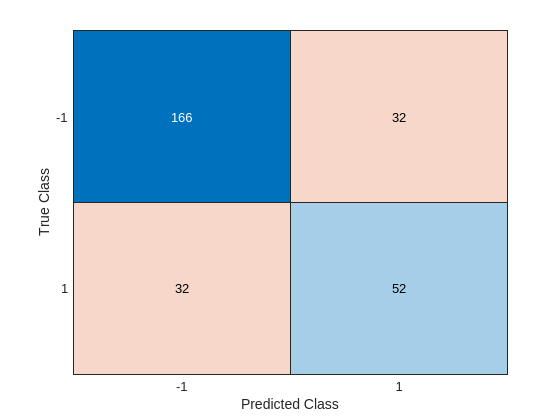

Full-sample Cross-Validation Fisher Exact Test: odds ratio=8.4297, p=8.0123e-14
Full-sample Cross-Validation Test Classification Accuracy (Group = -1): 0.83838
Full-sample Cross-Validation Test Classification Accuracy (Group = +1): 0.61905
Full-sample Cross-Validation Test Area Under ROC Curve: 0.80032
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Finished running modeling analysis
Time to to complete:11.0483 minutes


% fit model with CV hyperparameter optimization and selected significance testing
[model_results] = fit_and_evaluate_model(cfg);

8. View model results structure to evaluate model performance measures. The different fields contain different details about analysis parameters, data, and results.

- has_data - logical array of length n_subjects with values of 1 for all patients that were included in the analysis. Some patients may have been dropped due to not having any data after removing voxels that met the minimum damage threshold, and this can be used to identify which patients were dropped and which patients were retained for the analysis. 

- hp_opt - struct containing hyper-parameter optimization settings

- method - ensemble method 

- roc_auc - the obsreved area under the ROC curve for the full inferential model

- classrate - a 1x3 array containing classification rates: classrate(1) contains the classification rate for the group labeled "-1", classrate (2) contains the classification rate for the group labeled (1) , and classrate(3) contains the classification rate for all observations.  

- pred_y - fitted behavioral scores from the full-sample model (i.e., within-sample model "predictions").

- pred_score - predicted scores for the positive class (i.e., class labeled +1) - these are used to determine the final predicted class labels

- obs_y - observed behavioral scores, in this case standardized. Note that it has 518 rows, while the original input had 527 row, indicating 9 patients were removed due to no longer having any lesion data after trimming columns with insufficient observations. The patients that were removed from the original cfg.Y will have values of 0 in model_results.has_data.

- coeff - out-of-bag permutation predictor importances - see documentation for oobPermutedPredictorImportance(). If method was not "Bag", then these would be predictor importances - see documentation for predictorImportance().

- X - final predictor matrix after trimming columns with insufficient data. Since cfg.stacked_model == 1, no patients were dropped even if they had no non-zero data.

- X_ind - indices mapping the columns in the final predictor matrix model_results.X to the colulmns in the original predictor matrix cfg.X, i.e., the columns included in model_results.X are given by: model_results.X = cfg.X(model_results.X_ind)

- rng_seed - information about the rng seed and state (for reproducibility) 

- cfg - the cfg structure containing analysis parameters and details for reproducibility

% View contents of model_results structure
model_results

model_results = struct with fields:
            has_data: [282×1 double]
                  Cx: [3.3535 3.5382 3.3661 3.1101 2.0746 2.3641 6.8451 2.3525 3.3647 4.1005 2.4485 1.6984 3.0738 10.4148 10.4034 13.5349 12.8281 11.8565 8.5659 6.4375 3.9996 3.1078 2.7853 1.9888 2.9472 5.9531 3.5339 8.4011 6.8061 5.5985 1.9396 … ]
                  Sx: [16.3137 13.8785 13.7953 15.0828 10.5843 12.1543 18.9462 10.9897 14.2148 13.8712 13.5901 10.1893 14.5431 24.9097 25.2349 29.3314 26.8646 27.7578 22.6977 18.6513 14.3362 13.4263 12.7046 10.8302 11.9745 17.0459 15.2823 23.1526 … ]
              hp_opt: [1×1 struct]
              method: 'Bag'
             n_learn: 201
             roc_auc: 0.9953
           classrate: [0.9899 0.9524 0.9787]
              pred_y: [282×1 double]
          pred_score: [282×1 double]
               obs_y: [282×1 double]
    opt_score_thresh: 0.5775
               coeff: [-0.0548 0.0208 0.0532 -0.0389 -0.1173 -0.0654 0.1780 -0.0152 -0.0059 -0.0643 -0.1511 0.1138 -0.1302 0

By accessing fields in the model_results structure, you can evaluate the fit of the explanatory model. Note - these are *not* prediction performance estimates because these are from the full-sample model, and can be influenced by over-fitting. 

% Display model fit statistics for in-sample explanatory model 
disp(['Explanatory Model Classification Rate (Group = -1): ' num2str(model_results.classrate(1))]);

Explanatory Model Classification Rate (Group = -1): 0.9899


disp(['Explanatory Model Classification Rate (Group = +1): ' num2str(model_results.classrate(2))]);

Explanatory Model Classification Rate (Group = +1): 0.95238


disp(['Explanatory Model Classification Rate (Overall): ' num2str(model_results.classrate(3))]);

Explanatory Model Classification Rate (Overall): 0.97872


disp(['Explanatory Model Area under ROC Curve: ' num2str(model_results.roc_auc)]);

Explanatory Model Area under ROC Curve: 0.99531


Cross-validation test results and prediction performance estimates are in the cv_results structure saved into the output directory.

% Load cross-validation results for cross-validation test results
load(fullfile(cfg.out_dir, 'cv_results.mat'));

% Display model fit statistics from full sample cross-validation test results
disp(['Full-Sample Cross-validation Fisher Exact Test: OR=' num2str(cv_results.all.fisher_stat.OddsRatio) ', p=' num2str(cv_results.all.fisher_pval)]);

Full-Sample Cross-validation Fisher Exact Test: OR=8.4297, p=8.0123e-14


disp(['Full-Sample Cross-validation Classification Rate (Group = -1): ' num2str(cv_results.all.confusion.NormalizedValues(1,1) ./ (cv_results.all.confusion.NormalizedValues(1,2) + cv_results.all.confusion.NormalizedValues(1,1)))]);

Full-Sample Cross-validation Classification Rate (Group = -1): 0.83838


disp(['Full-Sample Cross-validation Classification Rate (Group = +1): ' num2str(cv_results.all.confusion.NormalizedValues(2,2) ./ (cv_results.all.confusion.NormalizedValues(2,2) + cv_results.all.confusion.NormalizedValues(2,1)))]);

Full-Sample Cross-validation Classification Rate (Group = +1): 0.61905


disp(['Full-Sample Cross-validation Area Under ROC Curve: ' num2str(cv_results.all.roc_auc)]);

Full-Sample Cross-validation Area Under ROC Curve: 0.80032


Note that the classification rate for the group labeled as +1 (i.e., patients with deficit) from the full-sample cross-validation test is substantially lower than the classification rate obtained from the full explanatory model (i.e., 0.59 vs. 0.74), as is the area under the ROC curve (i.e., 0.85 vs. 0.92), indicating that the performance measures from the full model are optimistically biased and likely reflect overfitting. Nonetheless, the cross-validation test indicated that the association between the predicted and observed group labels was highly statistically significant (p<0.001). We can therefore conclude that the model is capturing a meaningful relationship between regional damage and deficits in fluent speech. 

9. To evaluate *prediction* performance, load the cv_results.mat file from the output directory and view the contents.

- train_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be train_set(:, 1, 3), patients included in the training set have values equal to 1, and patients not in the training set for that fold for that repeat have values equal to 0.

- test_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be test_set(:, 1, 3), patients included in the test set have values equal to 1, and patients not in the test set for that fold for that repeat have values equal to 0.

- avg - subfield containing model coefficients and performance estimates averaged across folds

- coeff - n_voxels-by-repeat-by-fold matrix of model coefficients, analogous to the corresponding field in model_results

- all - subfield containing out-of-sample predictions for all folds within each repeat along with a confusion matrix and Fisher Exact Test results computed from the mode (across repeats) out-of-sample predictions for all observations (i.e., collapsed across folds and repeats) 

- pred_y - n_subjects-by-repeat-by-fold matrix of predicted behavioral scores for each test set in each fold and each repeat. For each fold within each repeat, patients that were in the training set have values equal to NaN, while patients in the test set have values equal to their predicted behavioral scores. 

- obs_y - same as pred_y, but with observed scores.

- classrate - an n_repeats-by-n_folds-by-3 matrix containing classification rates: classrate(1) contains the classification rate for the group labeled "-1", classrate (2) contains the classification rate for the group labeled (1) , and classrate(3) contains the classification rate for all observations.  

- roc_auc - an n_repeats-by-n_folds matrix containing area under the ROC curve for each fold and repeat

- pred_score - an n_subject-by-n_repeats-by-n_folds matrix predicted scores for the positive class (label = 1)

To evaluate the cross-validation results, we can plot the performance for the held-out patients across repeats and folds of the cross-validation analysis.

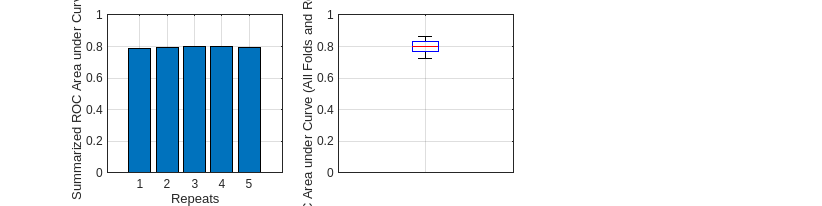

% Plot performance
clf;
subplot(1,3,1); 
bar(cv_results.avg.roc_auc);
set(gca, 'XtickLabel', {'1','2','3','4','5'});
xlabel('Repeats'); grid on;
ylabel('Summarized ROC Area under Curve')
subplot(1,3,2);
boxplot(cv_results.roc_auc(:)); grid on;
hold on; ylabel('ROC Area under Curve (All Folds and Repeats)');
set(gca, 'YLim', [0, 1]); set(gca, 'XtickLabel', '');
set(gcf, 'position', [0, 0, 1000, 250]); grid on;

The median area under the ROC curve across all folds and repeats was 0.86, indicating good classification performance.

Evaluate predictor importances for the full model and for the cross-validation models. Here, we plot the top 10 predictors based on the out-of-bag permutation predictor importance values. The top 10 for the full model and for the summarized cross-validation models are highly similar. We also make a scatterplot of the full importances from the full model and the summarized cross-validation models, showing that the predictor importances are in general highly similar. 

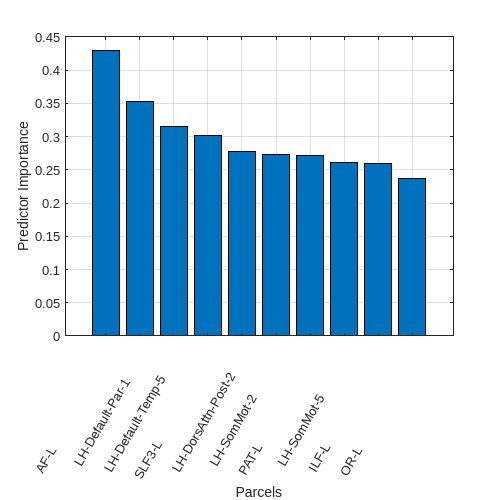

% Load file containing parcel names
load(fullfile(parcel_dir, 'parcel_names.mat'));
parcel_names = parcel_names(model_results.X_ind); % Subset only ROIs that were included in the analyses
parcel_names = replace(parcel_names, '_', '-');

% Get top 10 most important parcels
[ranked_parcels, rank_inds] = sort(model_results.coeff, 'descend');
ranked_names = parcel_names(rank_inds);
top10 = ranked_parcels(1:10);
top_names = ranked_names(1:10);

% Plot predictor importances
clf;
bar(top10); set(gca, 'Xtick', 1:1:length(top10)); 
xlabel('Parcels'); ylabel('Predictor Importance'); grid on;
set(gca, 'XtickLabel', top_names); set(gca, 'XtickLabelRotation', 60)

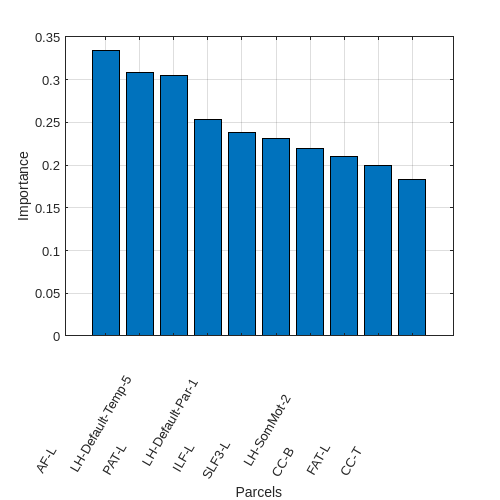


% Get most important predictors from cross-validation models 

% Get top 10 most important parcels from median coefficients
[ranked_parcels, rank_inds] = sort(mean(cv_results.avg.coeff,2), 'descend');
ranked_names = parcel_names(rank_inds);
top10 = ranked_parcels(1:10);
top_names = ranked_names(1:10);

% Plot predictor importances
clf;
bar(top10); set(gca, 'Xtick', 1:1:length(top10)); 
xlabel('Parcels'); ylabel('Importance'); grid on;
set(gca, 'XtickLabel', top_names); set(gca, 'XtickLabelRotation', 60)
grid on;

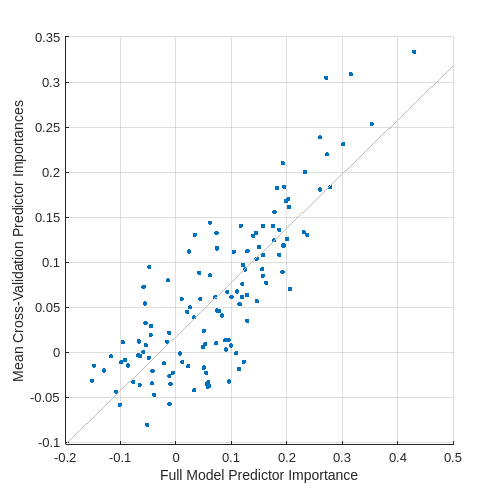


% Scatterplot of predictor importances from full vs. cros-validation models
clf;
scatter(model_results.coeff, mean(cv_results.avg.coeff,2), 50, '.'); lsline;
grid on; xlabel('Full Model Predictor Importance'); ylabel('Mean Cross-Validation Predictor Importances');
set(gcf, 'position', [0, 0, 500, 500]); grid on;